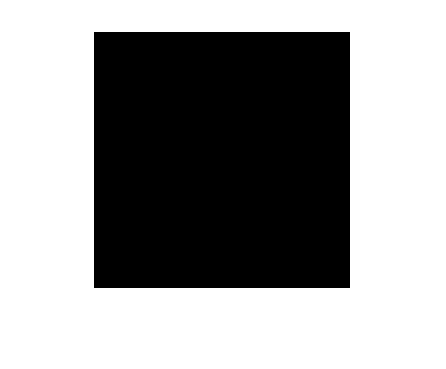

rng(2);

I = double(imread("barbara256.png"));
imshow(I/255);
I_final = double(zeros(256, 256));
I_n = zeros(256, 256);
W = @(x) dwt2(x, 'db1');
%WT = @(x) idwt2(x, 'db1');
Phi= randn(32, 64);
A = Phi;
for i = 1:249
    i
    for j =1:249
        J = I(i:i+7,j:j+7);
        x = reshape(J', [], 1);
        y = Phi*x; 
        theta_pred = ISTA2(y, A, W);
        x_pred = dwt2(theta_pred, 'db1');
        I_final(i:i+7,j:j+7) = I_final(i:i+7,j:j+7)+x_pred;
        I_n(i:i+7,j:j+7) = I_n(i:i+7,j:j+7)+1;
    end
    
end

I_final = I_final./I_n;
imshow(I_final/255);

I1 = double(imread("goldhill.png"));
imshow(I1/255);
I1 = I1(1:256,1:256);
imshow(I1/255);
I1_final = double(zeros(256, 256));
I1_n = zeros(256, 256);
for i = 1:249
    i
    for j =1:249
        J1 = I1(i:i+7,j:j+7);
        x1 = reshape(J1', [], 1);
        y1 = Phi*x1; 
        theta_pred1 = ISTA2(y1, A, W);
        x1_pred = dwt2(theta_pred1, 'db1');
        I1_final(i:i+7,j:j+7) = I1_final(i:i+7,j:j+7)+x
        1_pred;
        I1_n(i:i+7,j:j+7) = I1_n(i:i+7,j:j+7)+1;
    end
    
end

I1_final = min(zeros(256,256)+255,I1_final./I1_n);
imshow(I1_final/255);


